close all; clear; clc
dev = serialport("COM3",9600,"Timeout",60);
CMD_FREQUENCY = 3;
CMD_SWEEP_PARAMETERS = 6;
CMD_SWEEP = 9;

frequency = 800; % MHz
power = 0;

flush(dev)
write(dev,[CMD_FREQUENCY 0],"int8")
read(dev,3,'char')

ans = 'OK '

write(dev,[frequency power],'int16')
read(dev,3,'char')

ans = 'OK '

fmin = 100; % MHz
fmax = 4100; % MHz
fstep = 1; % MHz
texp = 60; % us
power = 3;
phase = 0;
n = (fmax-fmin)/fstep;
f = fmin:fstep:fmax-1;

flush(dev)
write(dev,[CMD_SWEEP_PARAMETERS 0],"int8")
read(dev,3,'char')

ans = 'OK '

write(dev,[fmin fmax fstep texp power phase],'int16')
read(dev,3,'char')

ans = 'OK '


write(dev,[CMD_SWEEP 0],"int8")
tic
data = read(dev,n*2+1,'int16');
toc

Elapsed time is 0.417027 seconds.


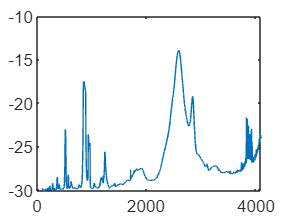

mag = data(1:2:end-1)/2048*30;
% mag = 10.^(mag/20);
pha = data(2:2:end-1)/2048*90;
locks = data(end);
plot(f,mag)

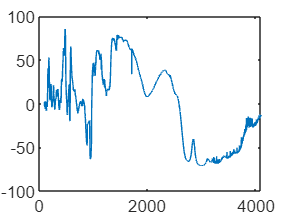

plot(f,pha)